# Raiz para sistemas no lineales

Carlos Arturo Aristizábal lopez

Juan José Mejía Sánchez

Santiago Escobar Grajales

Sebastian Bernal Ramirez

Jorge Enrique Rincón Soto

## Ejercicio:

Encontrar las raices o la raiz de los siguientes sistemas no lineales:


$$\begin{array}{l}
4x^2 +7\textrm{xy}=14\;\;\\
6x^2 y-3y=11
\end{array}$$


Organizamos las ecuaciones para tener una conjetura inicial e igulamos o cero:


$$\begin{array}{l}
4x^2 +7\textrm{xy}-14=0\\
6x^2 y-3y-11=0
\end{array}$$


En primera instancia vamos a encontrar las ecuaciones utilizando las poderozas herramientas que ofrece MATLAB.

Para que MATLAB reconozca que estamos utilizando sistemas no lineales vamos a utilizar el simbolo @ seguido de las variables contenidas, despues la ecuación.

Para comodidad y entendimiento vamos a decir que la primera ecuación es $f\left(x,y\right)$ y la segunda ecuación es $g\left(x,y\right)$


$$\begin{array}{l}
f=@\left(x,y\right)\;\;4x^2 +7\textrm{xy}-14\\
g=@\left(x,y\right)\;6x^2 y-3y-11
\end{array}$$


f = @(x,y) (4.*x.^2)+7.*x.*y-14

f = function_handle with value:
    @(x,y)(4.*x.^2)+7.*x.*y-14


g = @(x,y) (6.*x.^2*y)-3.*y-11

g = function_handle with value:
    @(x,y)(6.*x.^2*y)-3.*y-11


La representación grafica es de gran ayuda para vizualizar puntos aproximados a los cortes y poder iniciar el analisis.

Para graficar las ecuaciones dadas utilizamos la función **fimplicit**. Tomar dos intervalos aleatoreos, por ejemplo [-3 3] y verificar si se vizualiza un corte.

fimplicit(f,[-100 100])
hold on
fimplicit(g,[-100 100])

hold off
grid on

El mensaje de alerta nos sugiere que para mejorar el rendimiento, vectoricemos las ecuaciones para que devuelva una salida con el mismo tamaño y forma que los argumentos de entrada.

Vamos a tratar estas ecuaciones como vectores, para esto tanto $x$ y $y$ deben estar representadas como dos elementos de un vector $w$ de la siguiente forma:

ecuacionVectorial = @(w) [f(w(1),w(2));g(w(1),w(2))]

ecuacionVectorial = function_handle with value:
    @(w)[f(w(1),w(2));g(w(1),w(2))]


Observamos de nuevo la grafica y seleccionamos dos puntos cercanos de donde vizualizamos que cortan las dos ecuaciones, por ejemplo [-2.5   -2] y lo asignamos a una variable $\textrm{w0}$

w0 = [-2 1]

w0 =     -2     1


Para resolver este sistema de dos ecuaciones no lineales y despues de tener todo en terminos de vectores utilizamos la función fsolve y asignamos el resultado a una variable resultante:

raizVectorial = fsolve(ecuacionVectorial,w0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


raizVectorial =    -2.2537    0.4004


El resultado graficamente se ve asi:

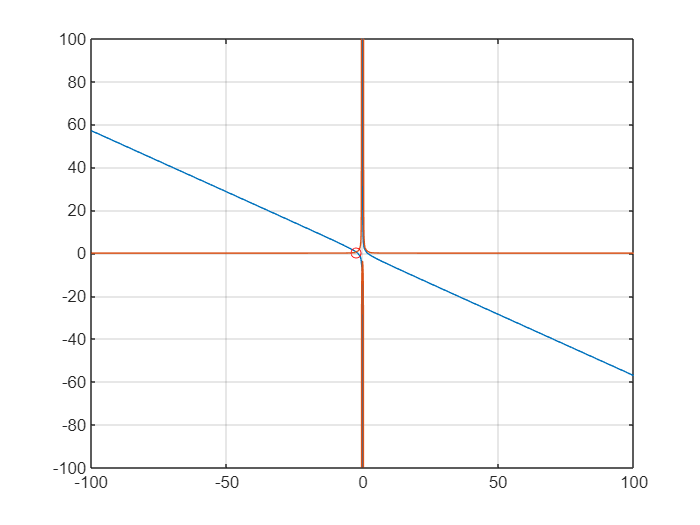

hold on
plot(raizVectorial(1),raizVectorial(2),"ro")
hold off

# Método de NEWTON-RAPHSON

syms x y

% Definir las funciones
f1 = 4 * x^2 + 7 * x * y - 14;
f2 = 6 * x^2 * y - 3 * y - 11;

% Crear la matriz de funciones F y la Jacobiana J
F = [f1; f2];
J = jacobian(F, [x, y]);

% Convertir F y J a funciones manejables numéricamente
F_func = matlabFunction(F, 'Vars', [x, y]);
J_func = matlabFunction(J, 'Vars', [x, y]);

% Condiciones iniciales
x_val = 2;
y_val = 7;

% Iteraciones del método de Newton
for i = 0:10  % Se realizan 11 iteraciones en total
    % Evaluar F y J en los valores actuales
    F_eval = F_func(x_val, y_val);
    J_eval = J_func(x_val, y_val);
    
    % Calcular el delta usando el método de Newton
    delta = J_eval \ F_eval;  % Resolver el sistema J*delta = F
    
    % Encabezado de la tabla
    fprintf('%-10s %-15s %-15s %-15s %-15s\n', 'Iteración', 'x', 'y', 'f1(x, y)', 'f2(x, y)');
    % Imprimir resultados de la iteración
    fprintf('%s\n', repmat('-', 1, 70));
    fprintf('%-10d %-15.6f %-15.6f %-15.6f %-15.6f\n', ...
            i, x_val, y_val, F_eval(1), F_eval(2));
    
    % Actualizar los valores de x y y
    x_val = x_val - delta(1);
    y_val = y_val - delta(2);
end

Iteración  x               y               f1(x, y)        f2(x, y)       


----------------------------------------------------------------------


0          2.000000        7.000000        100.000000      136.000000     


Iteración  x               y               f1(x, y)        f2(x, y)       


----------------------------------------------------------------------


1          2.198582        -1.064843       -11.052965      -38.688649     


Iteración  x               y               f1(x, y)        f2(x, y)       


----------------------------------------------------------------------


2          1.755963        -0.055179       -2.344626       -11.855304     


Iteración  x               y               f1(x, y)        f2(x, y)       


----------------------------------------------------------------------


3          1.272090        0.673361        -1.531116       -6.482233      


Iteración  x               y               f1(x, y)        f2(x, y)       


----------------------------------------------------------------------


4          -4.394912       10.321621       -254.277292     1154.223226    


Iteración  x               y               f1(x, y)        f2(x, y)       


----------------------------------------------------------------------


5          -3.853222       2.709412        -27.690479      222.236792     


Iteración  x               y               f1(x, y)        f2(x, y)       


----------------------------------------------------------------------


6          -3.032644       1.321985        -5.276050       57.983273      


Iteración  x               y               f1(x, y)        f2(x, y)       


----------------------------------------------------------------------


7          -2.503055       0.699062        -1.187394       13.181753      


Iteración  x               y               f1(x, y)        f2(x, y)       


----------------------------------------------------------------------


8          -2.290011       0.447315        -0.193882       1.732777       


Iteración  x               y               f1(x, y)        f2(x, y)       


----------------------------------------------------------------------


9          -2.254648       0.401712        -0.006286       0.047331       


Iteración  x               y               f1(x, y)        f2(x, y)       


----------------------------------------------------------------------


10         -2.253675       0.400375        -0.000005       0.000037       


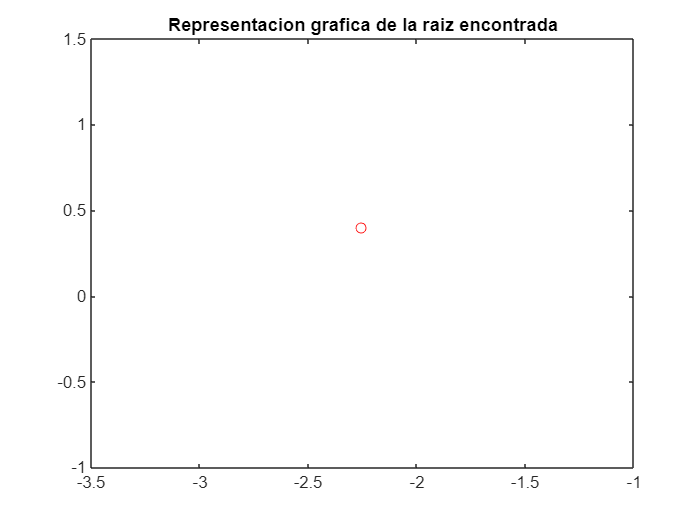

plot(x_val,y_val,"ro")
title("Representacion grafica de la raiz encontrada")

**Conclusión:** Se puede observar que en la iteración numero 10 la coordenada $\left(x,y\right)\;\mathrm{es}:\left(-2\ldotp 253675,0\ldotp 400375\right)$ que corresponde a una de las raices de las dos ecuaciones no lineales dadas.